clear;
load uspsDigits.mat;

% centroid metoden
disp('new part')

new part


randImgIndex = randi(2007)

randImgIndex = 1818

results = zeros(10,1);
sumDigit = zeros(16,16,10);
for dig = 0:9
    indexDigit = find(trainAns == dig);
    
    for c = 1:length(indexDigit)
        indexValue = indexDigit(c);
        trainDigits(:,:,indexValue);
        sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + trainDigits(:,:,indexValue);
    end
    meanDigit = sumDigit./length(indexDigit);
    tempDiff = abs(norm(meanDigit(:,:,dig + 1) - testDigits(:,:,randImgIndex)));
    results(dig + 1) = tempDiff;
end
results

results =     5.0169
    4.7923
    4.0944
    3.5498
    2.8545
    3.5820
    4.5549
    2.7150
    3.1794
    1.6163


[M,I] = min(results);
minDigit = I-1

minDigit = 9

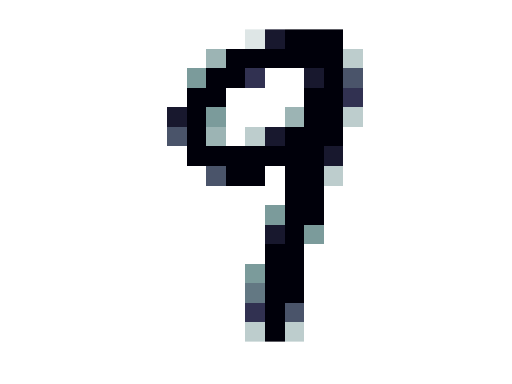

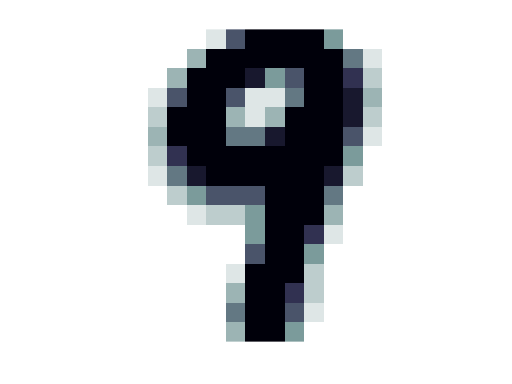

ima(testDigits(:,:,randImgIndex))
ima(sumDigit(:,:,minDigit + 1))

% ladda centroider i centroidDigit
disp('new part')

new part


centroidDigit = zeros(16,16,10);
for digit = 0:9;
    indexDigit = find(trainAns == digit);
    for c = 1:length(indexDigit)
        indexValue = indexDigit(c);
        centroidDigit(:,:,digit + 1) = centroidDigit(:,:,digit + 1) + trainDigits(:,:,indexValue);
    end
    centroidDigit(:,:,digit + 1) = centroidDigit(:,:,digit + 1)./length(indexDigit);
end

centroidResults = zeros(length(testAns), 2);
centroidResults(:, 1) = testAns;

for currentIndex = 1:length(testAns)

    currentResult = zeros(10,1);

    for digit = 0:9
        currentResult(digit + 1) = abs(norm(centroidDigit(:,:,digit + 1) - testDigits(:,:,currentIndex)));
    end
    currentResult;
    [~,I] = min(currentResult);
    centroidResults(currentIndex,2) = I-1;
end
centroidResults

centroidResults =      9     9
     6     2
     3     3
     6     2
     6     0
     0     0
     0     0
     0     0
     6     6
     9     9


amountWrong = zeros(10,1);
procentAndel = zeros(10,1);

for digit = 0:9
    allOfDigit = find(centroidResults(:,1) == digit);
    for index = 1:length(allOfDigit)
        indexOfCurrent = allOfDigit(index);
        if centroidResults(indexOfCurrent,1) ~= centroidResults(indexOfCurrent,2)
            amountWrong(digit + 1) = amountWrong(digit + 1) + 1;
        end
    end
    procentAndel(digit +1) = amountWrong(digit+1)/(length(find(testAns == digit)));
end

procentAndel.*100

ans =    17.5487
    4.5455
   31.8182
   30.1205
   29.0000
   33.1250
   19.4118
   19.7279
   31.3253
   19.7740


amountWrong

amountWrong =     63
    12
    63
    50
    58
    53
    33
    29
    52
    35


% first closest neighbooors 
disp('new part')

new part



%kolTrainDigits = reshape(trainDigits, [256, 1, 7291]);
neighboorResults = zeros(length(testAns), 2);
neighboorResults(:, 1) = testAns;


for testIndex = 1:length(testAns)
    savedIndex = 0;
    savedDiff = 1e3;
    for trainIndex = 1:length(trainAns)
        tempDiff = abs(norm(testDigits(:,:,testIndex) - trainDigits(:,:,trainIndex)));
        if tempDiff < savedDiff
            savedDiff = tempDiff;
            neighboorResults(testIndex, 2) = trainAns(trainIndex);
        end
    end
end 
neighboorResults

neighboorResults =      9     9
     6     6
     3     3
     6     6
     6     6
     0     0
     0     0
     0     0
     6     6
     9     9


amountWrong = zeros(10,1);
procentAndel = zeros(10,1);

for digit = 0:9
    allOfDigit = find(neighboorResults(:,1) == digit);
    for index = 1:length(allOfDigit)
        indexOfCurrent = allOfDigit(index);
        if neighboorResults(indexOfCurrent,1) ~= neighboorResults(indexOfCurrent,2)
            amountWrong(digit + 1) = amountWrong(digit + 1) + 1;
        end
    end
    procentAndel(digit +1) = amountWrong(digit+1)/(length(find(testAns == digit)));
end

procentAndel.*100

ans =     1.6713
    3.7879
   10.1010
   10.8434
    9.5000
    8.7500
    5.2941
    7.4830
    9.0361
    2.2599


amountWrong

amountWrong =      6
    10
    20
    18
    19
    14
     9
    11
    15
     4
